# LAB3 MATLAB Programming

涂峻绫(12213010) and 欧阳安男(12211831)

## Introduction

MATLAB is a powerful

## Results and Analysis

### 3.8

#### (a)

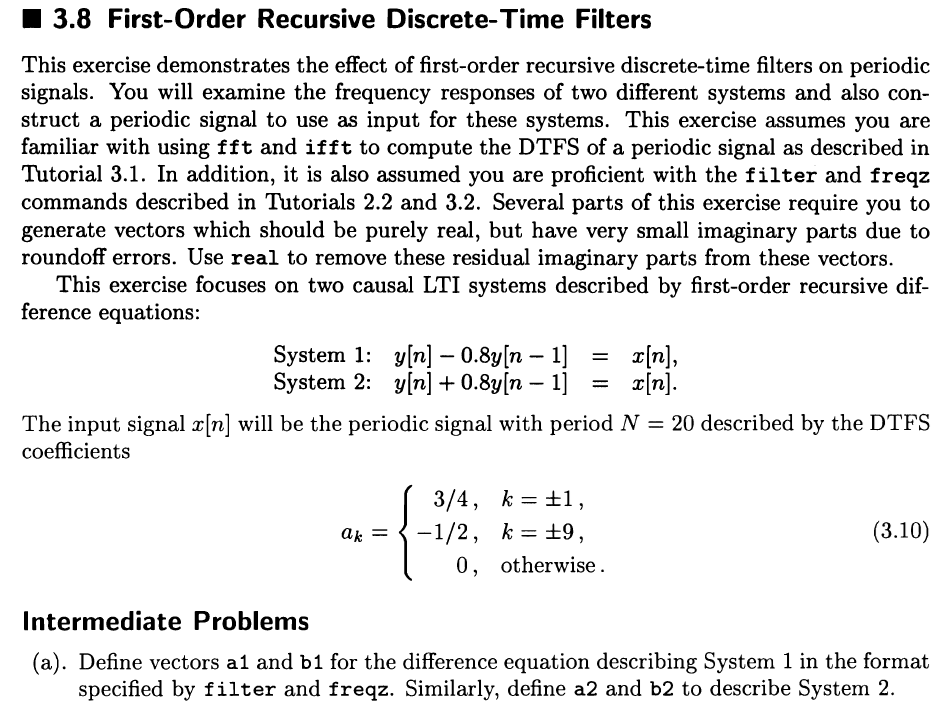

Initialize.

clear; clc; close all;

Create vectors $a_1,b_1$ and $a_2,b_2$.

a1 = [1 -0.8]

a1 =     1.0000   -0.8000


b1 = 1

b1 = 1

a2 = [1 0.8]

a2 =     1.0000    0.8000


b2 = 1

b2 = 1

#### (b)

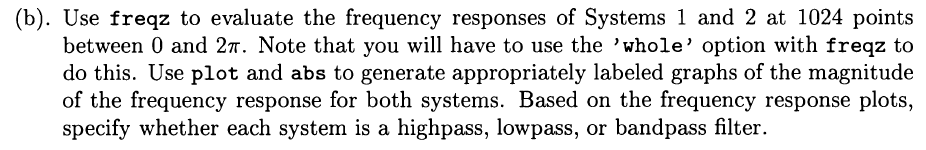

Calculate $H_1,\omega_1,H_2,\omega_2$.

[H1,omega1] = freqz(b1,a1,1024,'whole');
[H2,omega2] = freqz(b2,a2,1024,'whole');

Plot frequency responese for both systems.

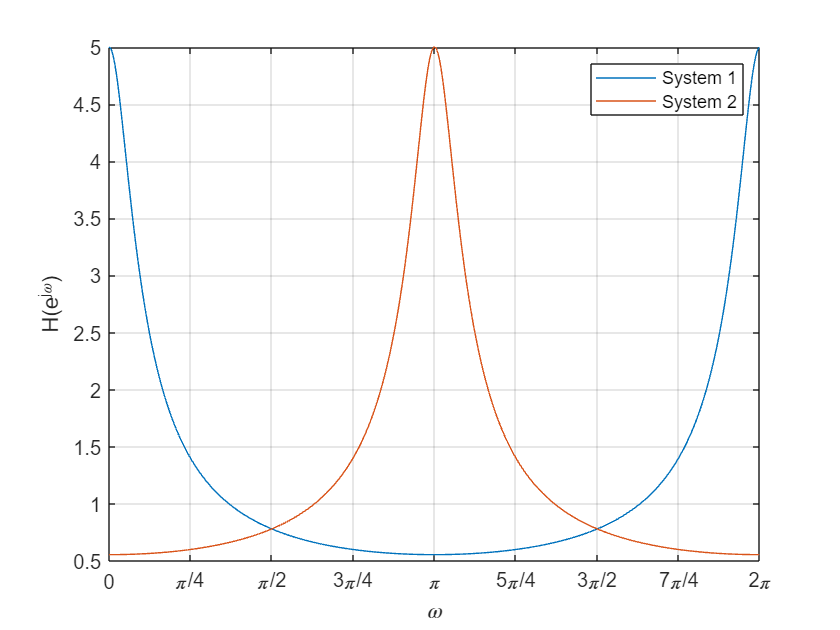

figure;
plot(omega1,abs(H1));
hold on;
plot(omega2,abs(H2));
grid on;
axis([0 2*pi ylim]);
xlabel('\omega');
ylabel('H(e^{j\omega})');
xticks(0:pi/4:2*pi);
xticklabels({'0' '\pi/4' '\pi/2' '3\pi/4' '\pi' '5\pi/4' '3\pi/2' '7\pi/4' '2\pi'});
legend('System 1','System 2');

The frequency responese for system 1 is high when $\omega$ is small and big so system 1 is both highpass and lowpass filter.

The frequency responese for system 2 is high when $\omega$ close to $\pi$ so system 2 is bandpass filter.

#### (e)

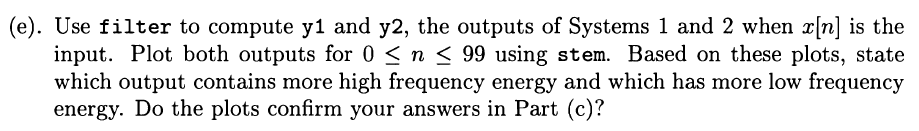

### 3.10

#### (a)

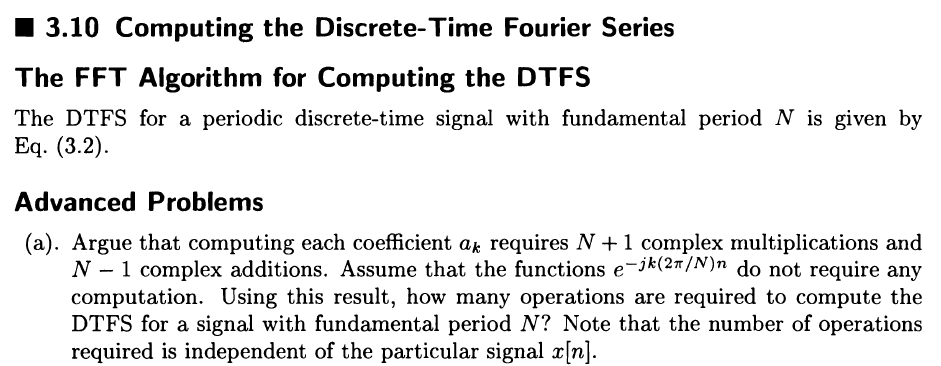

clear; clc; close all;

Need $N(N+1)$ complex multiplications and $N(N-1)$ complex additions.

#### (b)

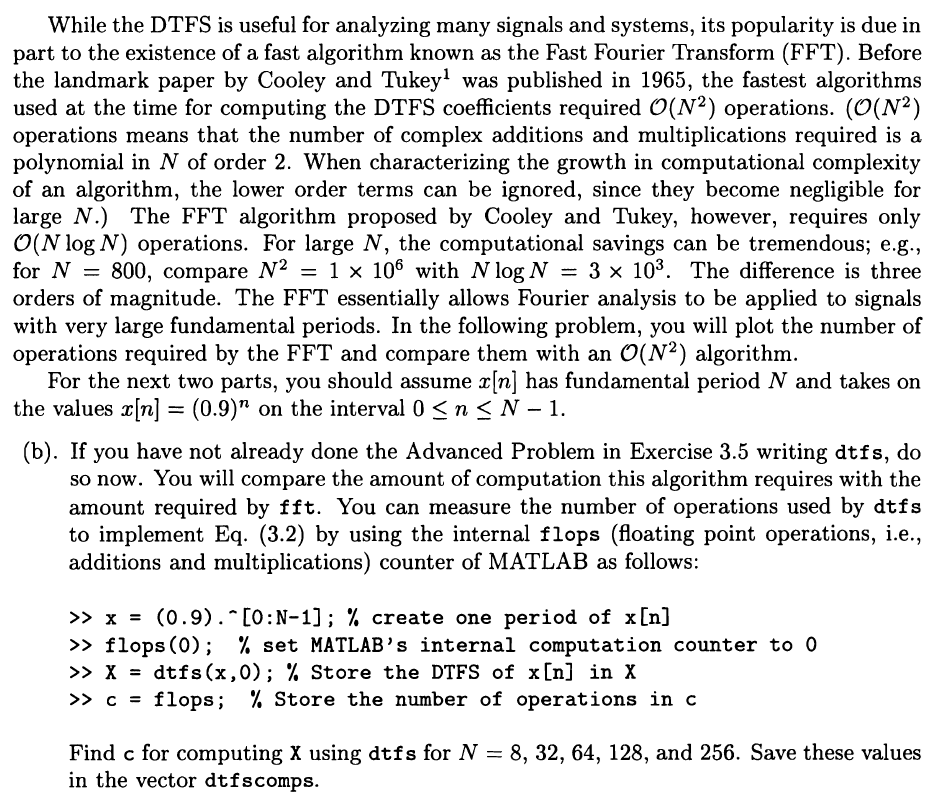

Since flops has been removed so use the execution time to be the substitude.

dtfscomps = zeros(1,5);
N_list = [8 32 64 128 256];
for i = 1:5
    N = N_list(i);
    x = (0.9).^(0:N-1);
    tic;
    X = dtfs(x,0);
    dtfscomps(i) = toc;
end

### Functions

Unit step function

function a = dtfs(x,n_init)
    m = zeros(length(x),length(x));
    for i = 1:length(x)
        for j = 1:length(x)
            m(j,i) = exp(-1i*2*pi/length(x)*(i-1)*(j+n_init-1))/length(x);
        end
    end
    a = x*m;
end

## Expeience

........................